% Initialize %
image_dir = "images/Fruit";
%images_all = Read_Images(image_dir, 'apple*.jpg');
red_apples_pattern = 'appletree_ripe*.jpg';
green_apples_pattern = 'appletree_raw*.jpg';

% Read images %
red_apples_images = Read_Images(image_dir, red_apples_pattern);

Reading images at - images\Fruit\appletree_ripe*.jpg
Number of images found in directory: 3
Read 3/3


green_apples_images = Read_Images(image_dir, green_apples_pattern);

Reading images at - images\Fruit\appletree_raw*.jpg
Number of images found in directory: 1
Read 1/1


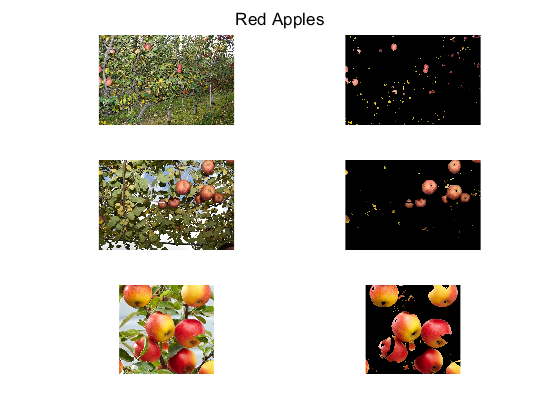


% Show Red Apples % - Color thresholding
Detect_Red_Apples(red_apples_images);
sgtitle("Red Apples");

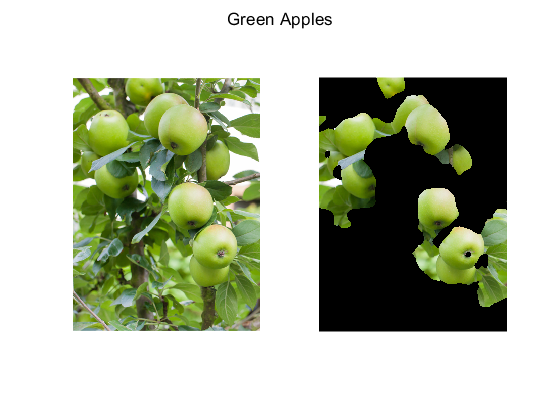


% Show Green Apples % - K-means Clustering

% resize the image so it runs faster
resized_img = imresize(green_apples_images{1}, 0.5);

debug = false;
use_color_only_segm = false;

m = Detect_Green_Apples_KMeansCluster(resized_img, debug, use_color_only_segm);
figure; subplot(1, 2, 1);
imshow(resized_img);
subplot(1, 2, 2);
imshow(m);
sgtitle("Green Apples");


%Detect_Green_Apples_FCMCluster(resized_img); % <-- Requires Add ons